clc;clear;clear all;
global X mu_xi  mu_X; 

altsinir_mKare=0; ustsinir_mKare=100;
altsinir_mevki=0; ustsinir_mevki=100;
altsinir_binaYasi=0; ustsinir_binaYasi=100;
 
evFiyati_altsinir=0; evFiyati_ustsinir=100;

%numerik girisler
mKare_xi=54; mevki_xi=83; binaYasi_xi=71;


  
%Numerik girislerin, girsi cikis uyelik fonk ,Bulanik kumelerin tanimlanmasi


%1. m kare Puaný girisine ait uyelik fonksiyonlari ve bulaniklaþtirma
ucgen(altsinir_mKare,0,20,40,ustsinir_mKare,mKare_xi); az_mKare_X=X; az_mKare_mu_X=mu_X; az_mKare_xi=mu_xi; 

mu_xi = 0

hold on;
ucgen(altsinir_mKare,30,50,70,ustsinir_mKare,mKare_xi); orta_mKare_X=X; orta_mKare_mu_X=mu_X; orta_mKare_xi=mu_xi;

mu_xi = 0.8000

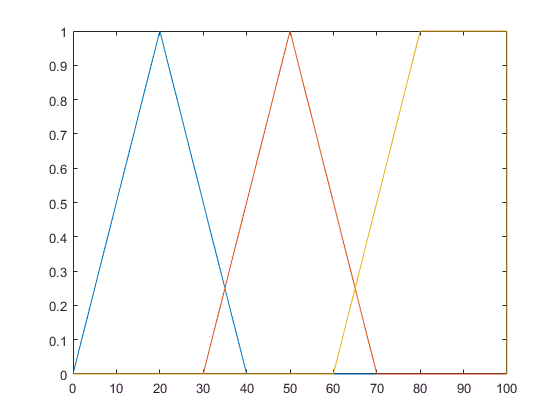

yamuk(altsinir_mKare,60,80,100,100,ustsinir_mKare,mKare_xi); cok_mKare_X=X; cok_mKare_mu_X=mu_X; cok_mKare_xi=mu_xi; 


figure;


%2. konum deðerlerine ait uyelik fonk girisleri...
ucgen(altsinir_mevki,0,20,40,ustsinir_mevki, mevki_xi); kotu_mevki_X=X; kotu_mevki_X_mu_X=mu_X; kotu_mevki_xi=mu_xi; 

mu_xi = 0

hold on;
ucgen(altsinir_mevki,30,50,70,ustsinir_mevki, mevki_xi); orta_mevki_X=X; orta_mevki_mu_X=mu_X; orta_mevki_xi=mu_xi; 

mu_xi = 0

yamuk(altsinir_mevki,60,80,100,100,ustsinir_mevki, mevki_xi); iyi_mevki_X=X; iyi_mevki_mu_X=mu_X; iyi_mevki_xi=mu_xi; 

figure;



%3. bina yasina ait uyelik fonk girisleri ..
ucgen(altsinir_binaYasi,0,20,40,ustsinir_binaYasi,binaYasi_xi); eski_binaYasi_X=X; eski_binaYasi_mu_X=mu_X; eski_binaYasi_xi=mu_xi; 

mu_xi = 0

hold on;
ucgen(altsinir_binaYasi,30,50,70,ustsinir_binaYasi,binaYasi_xi); orta_binaYasi_X=X; orta_binaYasi_mu_X=mu_X; orta_binaYasi_xi=mu_xi; 

mu_xi = 0

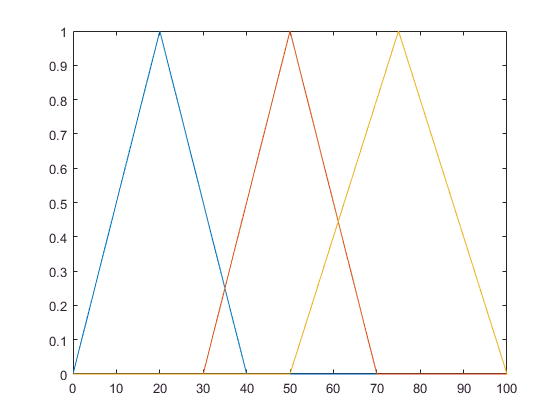

mu_xi = 0.8400

ucgen(altsinir_binaYasi,50,75,100,ustsinir_binaYasi,binaYasi_xi); yeni_binaYasi_manzara_X=X; yeni_binaYasi_mu_X=mu_X; yeni_binaYasi_xi=mu_xi; 

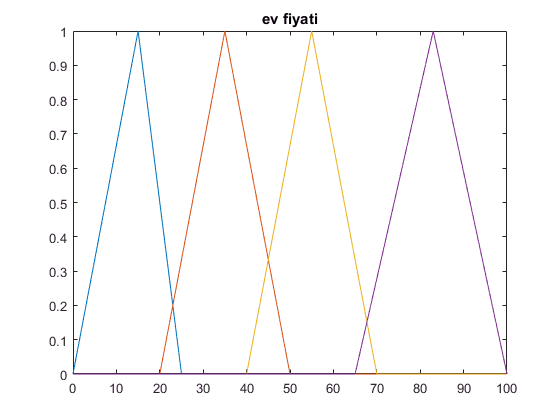


figure;

%ev fiyat tahmini cikis uyelik fonk
ucgen2(evFiyati_altsinir,0,15,25,evFiyati_ustsinir); uzucEvFiyat_z=X; ucuzEvFiyat_mu=mu_X;
hold on;
ucgen2(evFiyati_altsinir,20,35,50,evFiyati_ustsinir);  ortaEvFiyat_z=X;  ortaEvFiyat_mu=mu_X;
ucgen2(evFiyati_altsinir,40,55,70,evFiyati_ustsinir);  yuksekEvFiyat_z=X; yuksekEvFiyat_mu=mu_X;
ucgen2(evFiyati_altsinir,65,83,100,evFiyati_ustsinir); cokYuksekEvFiyat_z=X; cokYuksekEvFiyat_mu=mu_X;

title('ev fiyati')

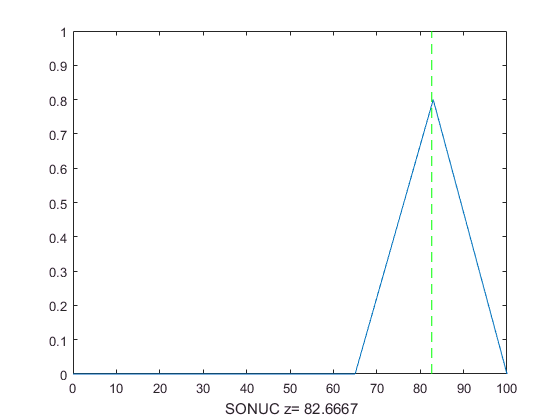

figure;


%Kurallarin tanimlanmasi ve gecerlilik derecelerin hesaplanmasi
mu_kural1=min(min(az_mKare_xi,kotu_mevki_xi),eski_binaYasi_xi);
mu_kural2=min(min(az_mKare_xi,kotu_mevki_xi),orta_binaYasi_xi);
mu_kural3=min(min(az_mKare_xi,kotu_mevki_xi),yeni_binaYasi_xi);

mu_kural4=min(min(az_mKare_xi,orta_mevki_xi),eski_binaYasi_xi);
mu_kural5=min(min(az_mKare_xi,orta_mevki_xi),orta_binaYasi_xi);
mu_kural6=min(min(az_mKare_xi,orta_mevki_xi),yeni_binaYasi_xi);

mu_kural7=min(min(az_mKare_xi,iyi_mevki_xi),eski_binaYasi_xi);
mu_kural8=min(min(az_mKare_xi,iyi_mevki_xi),orta_binaYasi_xi);
mu_kural9=min(min(az_mKare_xi,iyi_mevki_xi),yeni_binaYasi_xi);

mu_kural10=min(min(orta_mKare_xi,kotu_mevki_xi),eski_binaYasi_xi);
mu_kural11=min(min(orta_mKare_xi,kotu_mevki_xi),orta_binaYasi_xi);
mu_kural12=min(min(orta_mKare_xi,kotu_mevki_xi),yeni_binaYasi_xi);

mu_kural13=min(min(orta_mKare_xi,orta_mevki_xi),eski_binaYasi_xi);
mu_kural14=min(min(orta_mKare_xi,orta_mevki_xi),orta_binaYasi_xi);
mu_kural15=min(min(orta_mKare_xi,orta_mevki_xi),yeni_binaYasi_xi);

mu_kural16=min(min(orta_mKare_xi,iyi_mevki_xi),eski_binaYasi_xi);
mu_kural17=min(min(orta_mKare_xi,iyi_mevki_xi),orta_binaYasi_xi);
mu_kural18=min(min(orta_mKare_xi,iyi_mevki_xi),yeni_binaYasi_xi);

mu_kural19=min(min(cok_mKare_xi,kotu_mevki_xi),eski_binaYasi_xi);
mu_kural20=min(min(cok_mKare_xi,kotu_mevki_xi),orta_binaYasi_xi);
mu_kural21=min(min(cok_mKare_xi,kotu_mevki_xi),yeni_binaYasi_xi);

mu_kural22=min(min(cok_mKare_xi,orta_mevki_xi),eski_binaYasi_xi);
mu_kural23=min(min(cok_mKare_xi,orta_mevki_xi),orta_binaYasi_xi);
mu_kural24=min(min(cok_mKare_xi,orta_mevki_xi),yeni_binaYasi_xi);


mu_kural25=min(min(cok_mKare_xi,iyi_mevki_xi),eski_binaYasi_xi);
mu_kural26=min(min(cok_mKare_xi,iyi_mevki_xi),orta_binaYasi_xi);
mu_kural27=min(min(cok_mKare_xi,iyi_mevki_xi),yeni_binaYasi_xi);




mu_sonuc1=mu_kural1*ucuzEvFiyat_mu;
mu_sonuc2=mu_kural2*ucuzEvFiyat_mu;
mu_sonuc3=mu_kural3*ucuzEvFiyat_mu;

mu_sonuc4=mu_kural4*ucuzEvFiyat_mu;
mu_sonuc5=mu_kural5*ortaEvFiyat_mu;
mu_sonuc6=mu_kural6*ortaEvFiyat_mu;

mu_sonuc7=mu_kural7*ucuzEvFiyat_mu;
mu_sonuc8=mu_kural8*ortaEvFiyat_mu;
mu_sonuc9=mu_kural9*yuksekEvFiyat_mu;

mu_sonuc10=mu_kural10*ucuzEvFiyat_mu;
mu_sonuc11=mu_kural11*ortaEvFiyat_mu;
mu_sonuc12=mu_kural12*yuksekEvFiyat_mu;

mu_sonuc13=mu_kural13*ortaEvFiyat_mu;
mu_sonuc14=mu_kural14*ortaEvFiyat_mu;
mu_sonuc15=mu_kural15*yuksekEvFiyat_mu;

mu_sonuc16=mu_kural16*ortaEvFiyat_mu;
mu_sonuc17=mu_kural17*yuksekEvFiyat_mu;
mu_sonuc18=mu_kural18*cokYuksekEvFiyat_mu;

mu_sonuc19=mu_kural19*ucuzEvFiyat_mu;
mu_sonuc20=mu_kural20*ortaEvFiyat_mu;
mu_sonuc21=mu_kural21*yuksekEvFiyat_mu;

mu_sonuc22=mu_kural22*ortaEvFiyat_mu;
mu_sonuc23=mu_kural23*yuksekEvFiyat_mu;
mu_sonuc24=mu_kural24*cokYuksekEvFiyat_mu;

mu_sonuc25=mu_kural25*yuksekEvFiyat_mu;
mu_sonuc26=mu_kural26*cokYuksekEvFiyat_mu;
mu_sonuc27=mu_kural27*cokYuksekEvFiyat_mu;


%%%%%%%%%%%%%%%%

%birlestirme operatoru olarak max kullanilmistir 1. ÇIKIÞ
% mu_birlestirme1=max(max(max(max(max(mu_sonuc1, mu_sonuc2),max(mu_sonuc3,mu_sonuc4)),max(max(mu_sonuc5,mu_sonuc6),max(mu_sonuc7,mu_sonuc8))),max(max(max(mu_sonuc9,mu_sonuc10),max(mu_sonuc11,mu_sonuc12)),max(max(mu_sonuc13, mu_sonuc14),max(mu_sonuc15,mu_sonuc16)))),max(max(max(mu_sonuc17,mu_sonuc18),max(mu_sonuc19,mu_sonuc20)),max(mu_sonuc21,mu_sonuc22)));
% mu_birlestirme2=max(max(max(max(max(mu_sonuc23, mu_sonuc24),max(mu_sonuc25,mu_sonuc26)),max(max(mu_sonuc27,mu_sonuc28),max(mu_sonuc29,mu_sonuc30))),max(max(max(mu_sonuc31,mu_sonuc32),max(mu_sonuc33,mu_sonuc34)),max(max(mu_sonuc35, mu_sonuc36),max(mu_sonuc37,mu_sonuc38)))),max(max(max(mu_sonuc39,mu_sonuc40),max(mu_sonuc41,mu_sonuc42)),max(mu_sonuc43,mu_sonuc44)));
% mu_birlestirme3=max(max(max(max(mu_sonuc45, mu_sonuc46),max(mu_sonuc47,mu_sonuc48)),max(max(mu_sonuc49,mu_sonuc50),max(mu_sonuc51,mu_sonuc52))),max(max(max(mu_sonuc53,mu_sonuc54),max(mu_sonuc55,mu_sonuc56)),max(max(mu_sonuc57, mu_sonuc58),max(mu_sonuc59,mu_sonuc60))));
% mu_birlestirme4=max(max(mu_sonuc61,mu_sonuc62),max(mu_sonuc63,mu_sonuc64));
% mu_birlestirme=max(max(mu_birlestirme1,mu_birlestirme2),max(mu_birlestirme3,mu_birlestirme4));
mu_birlestirme1 = mu_sonuc1+mu_sonuc2+mu_sonuc3+mu_sonuc4+mu_sonuc5+mu_sonuc6+mu_sonuc7+mu_sonuc8+mu_sonuc9+mu_sonuc10+mu_sonuc11+mu_sonuc12+mu_sonuc13+mu_sonuc14+mu_sonuc15+mu_sonuc16+mu_sonuc17+mu_sonuc18+mu_sonuc19+mu_sonuc20;
mu_birlestirme2 = mu_sonuc21+mu_sonuc22+mu_sonuc23+mu_sonuc24+mu_sonuc25+mu_sonuc26+mu_sonuc27;
mu_birlestirme = mu_birlestirme1+mu_birlestirme2;
% length(mu_birlestirme)
% length(X)
% X=0:0.001:100
figure;
plot(X,mu_birlestirme);

%durulastirma operatoru olarak agirlik merkezi kullanilmistir
toplam_alan=sum(mu_birlestirme); 
if toplam_alan==0
    disp('Agýrlýk merkezi Yonteminde Toplam Alan Sifir')
end
z = ((sum(mu_birlestirme.*X))/(toplam_alan));
hold on;
line(z,0:0.01:1);
xlabel([' SONUC z= ', num2str(z)]);
 h=[z z z z z z z z z z z];

 line(h,0:0.1:1,'Color','green','LineStyle','--'); %durulaþtýrma sonucu